Linear Spike

center = .3+.4*rand();
spread = .2*rand();

my_pdf = @(p) linear_spike(p,center,spread);
my_cdf = @(p) linear_spike_cdf(p,center,spread);
my_inverse_cdf = @(p) linear_spike_inverse_cdf(p,center,spread);

% Non-Negativity of PDF
p_mesh = 0:.0001:1;
assert(sum(my_pdf(p_mesh)<0)==0)

% Normalization of PDF
    % To a Precision of one ten-thousandth
assert(abs(integral(my_pdf,0,1)-1)<1e-4)

% CDF Goes from 0 to 1
    % To a Precision of one ten-thousandth
assert(my_cdf(0)<1e-4)
assert(abs(my_cdf(1)-1)<1e-4)

% PDF is the Integral of the CDF
    % To a Precision of one ten-thousandth
for p_random = rand(1,7)
    assert(abs(integral(my_pdf,0,p_random)-my_cdf(p_random))<1e-4)
end

% Inverse CDF is the Inverse of the CDF
    % To a Precision of one ten-thousandth
for percentile_random = rand(1,7)
    assert(abs(my_cdf(my_inverse_cdf(percentile_random))-percentile_random)<1e-4)
end


Modified Beta

center = .5+.15*rand();
spread = .1*rand();

my_pdf = @(p) modified_beta(p,center,spread);
my_cdf = @(p) modified_beta_cdf(p,center,spread);
my_inverse_cdf = @(p) modified_beta_inverse_cdf(p,center,spread);

% Non-Negativity of PDF
p_mesh = 0:.0001:1;
assert(sum(my_pdf(p_mesh)<0)==0)

% Normalization of PDF
    % To a Precision of one ten-thousandth
assert(abs(integral(my_pdf,0,1)-1)<1e-4)

% CDF Goes from 0 to 1
    % To a Precision of one ten-thousandth
assert(my_cdf(0)<1e-4)
assert(abs(my_cdf(1)-1)<1e-4)

% PDF is the Integral of the CDF
    % To a Precision of one ten-thousandth
for p_random = rand(1,7)
    assert(abs(integral(my_pdf,0,p_random)-my_cdf(p_random))<1e-4)
end

% Inverse CDF is the Inverse of the CDF
    % To a Precision of one ten-thousandth
for percentile_random = rand(1,7)
    assert(abs(my_cdf(my_inverse_cdf(percentile_random))-percentile_random)<1e-4)
end

Modified Gaussian

center = .3+.4*rand();
spread = .1*rand();

my_pdf = @(p) modified_gaussian(p,center,spread);
my_cdf = @(p) modified_gaussian_cdf(p,center,spread);
my_inverse_cdf = @(p) modified_gaussian_inverse_cdf(p,center,spread);

% Non-Negativity of PDF
p_mesh = 0:.0001:1;
assert(sum(my_pdf(p_mesh)<0)==0)

% Normalization of PDF
    % To a Precision of one ten-thousandth
assert(abs(integral(my_pdf,0,1)-1)<1e-4)

% CDF Goes from 0 to 1
    % To a Precision of one ten-thousandth
assert(my_cdf(0)<1e-4)
assert(abs(my_cdf(1)-1)<1e-4)

% PDF is the Integral of the CDF
    % To a Precision of one ten-thousandth
for p_random = rand(1,7)
    assert(abs(integral(my_pdf,0,p_random)-my_cdf(p_random))<1e-4)
end

% Inverse CDF is the Inverse of the CDF
    % To a Precision of one ten-thousandth
for percentile_random = rand(1,7)
    assert(abs(my_cdf(my_inverse_cdf(percentile_random))-percentile_random)<1e-4)
end


Modified Rayleigh

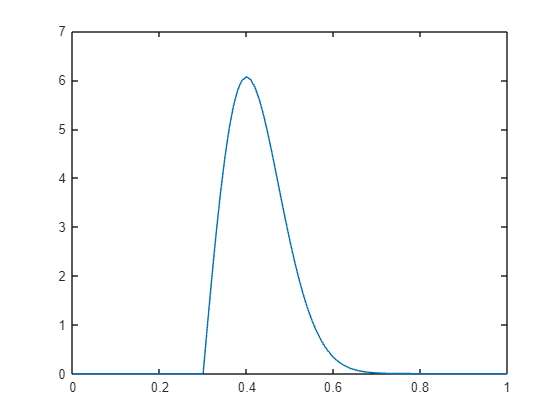

B = .1;

my_pdf = @(p) modified_rayleigh(p,B);
my_cdf = @(p) modified_rayleigh_cdf(p,B);
my_inverse_cdf = @(p) modified_rayleigh_inverse_cdf(p,B);

plot(0:.01:1,my_pdf(0:.01:1))


% Non-Negativity of PDF
p_mesh = 0:.0001:1;
assert(sum(my_pdf(p_mesh)<0)==0)

% Normalization of PDF
    % To a Precision of one ten-thousandth
assert(abs(integral(my_pdf,0,1)-1)<1e-4)

% CDF Goes from 0 to 1
    % To a Precision of one ten-thousandth
assert(my_cdf(0)<1e-4)
assert(abs(my_cdf(1)-1)<1e-4)

% PDF is the Integral of the CDF
    % To a Precision of one ten-thousandth
for p_random = rand(1,7)
    assert(abs(integral(my_pdf,0,p_random)-my_cdf(p_random))<1e-4)
end

% Inverse CDF is the Inverse of the CDF
    % To a Precision of one ten-thousandth
for percentile_random = rand(1,7)
    assert(abs(my_cdf(my_inverse_cdf(percentile_random))-percentile_random)<1e-4)
end